**Use this script to test, and comment changes made to functions**

Please list **What** changes made, **who** made the changes, **when** the changes were made

If there are errors please explain to the best of your ability what change resulted in that error or why the error is happening.

Remove above before submitting

**Tasmanian Devil Facial Tumor Disease Simulation**

This simulation aims to inform the populace of the danger that Devil Facial Tumor Disease (DFTD) has on the Tasmanian Devil population. DFTD is a transmissable cancer that takes the form of lumps of soft tissue around the mouth. DFTD is most often trasmitted by bites, when the teeth come into contact with the cancer tissue. Other ways of transmission include ingesting infected carcasses and sharing food.

This model utilises random walks and cellular automata to simulate the movement of the tasmanian devil population and the spread of the disease throughout it. The movement is governed by a 2-dimensional random walk that has dynamic weighting dictacted by the use of cellular automata. For any given cell (tasmanian devil), the weighting of the movement is adjusted based on the neighours surrounding it. This weighting will increase the chance for the cell to either move closer or further away from their neighbours depending on the time of year to reflect the change in behaviour during mating seasons.

Cellular autmomata is utilised to determine disease transmission and procreation during mating season. For any uninfected cells, the chance that they are infected in the next iteration of the simulation is determined by the number of surrounding infected cells.

%       N - Amount of iterations sim will run for.
%           if N = 1 then simulation runs for 1 week (dt = 1 week)
%       init_pos - Initial positions of every Tasmainian devil in sim, can
%                   use rand function to uniformally distribute tasmaninian
%                   devils over matrix  
A = 200; % size of sim
B = 300; % size of sim
N = 104; % two years
infected_percentage = .2;
sd  = 0.45; 
init_pos = rand(A,B)>0.999;
init_pos = init_pos + abs(2*(rand(A,B)>0.999));
infected = sum(sum(init_pos > 1));
pop = sum(sum(init_pos == 1));


Week 2 - Living: 118, Infected: 54.24%
Week 3 - Living: 118, Infected: 54.24%
Week 4 - Living: 118, Infected: 54.24%
Week 5 - Living: 118, Infected: 54.24%
Week 6 - Living: 118, Infected: 55.08%
Week 7 - Living: 118, Infected: 55.08%
Week 8 - Living: 118, Infected: 55.08%
Week 9 - Living: 118, Infected: 55.08%
Week 10 - Living: 118, Infected: 55.08%
Week 11 - Living: 124, Infected: 52.42%
Week 12 - Living: 125, Infected: 52.00%
Week 13 - Living: 131, Infected: 49.62%
Week 14 - Living: 138, Infected: 47.83%
Week 15 - Living: 144, Infected: 45.83%
Week 16 - Living: 147, Infected: 44.90%
Week 17 - Living: 163, Infected: 40.49%
Week 18 - Living: 169, Infected: 39.64%
Week 19 - Living: 188, Infected: 36.17%
Week 20 - Living: 196, Infected: 35.71%
Week 21 - Living: 196, Infected: 37.76%
Week 22 - Living: 196, Infected: 38.78%
Week 23 - Living: 196, Infected: 39.80%
Week 24 - Living: 196, Infected: 40.31%
Week 25 - Living: 196, Infected: 40.31%
Week 26 - Living: 196, Infected: 42.35%
Week 27 

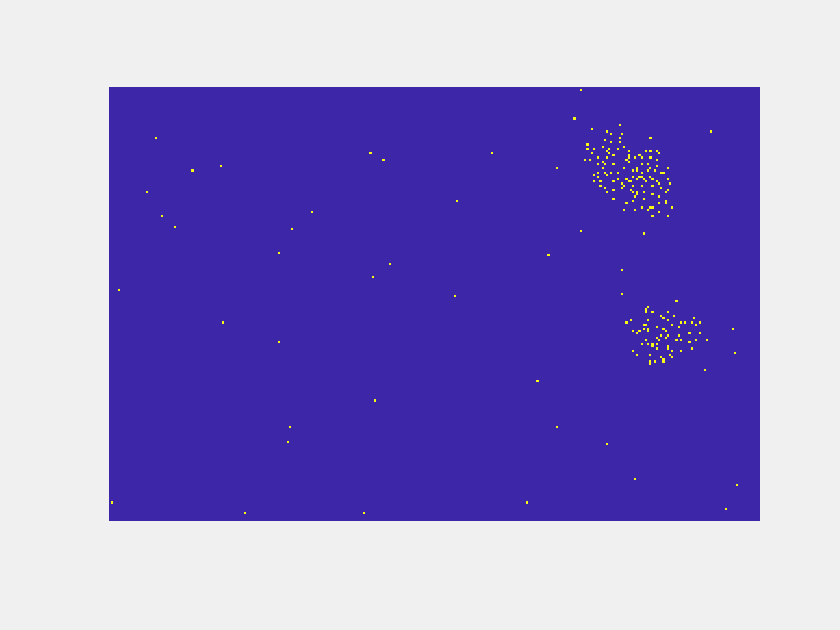


[positions,population,infection_percentage] = Tasmianian_Devil_sim(N, init_pos);

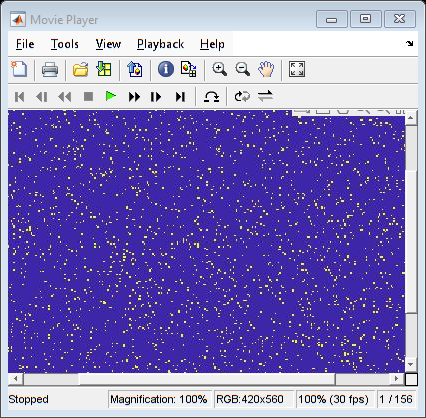

implay Simulation_vid.avi